# Row Entries Table

This widget is intended to enable display and editing of simple lists when each item (row) has multiple attributes (columns) to configure. You can add or remove rows using the buttons. You may optionally enable ordering buttons to move items up and down the list.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 220]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

Create and configure the widget:

rtWidget = wt.RowEntriesTable(gridObj);
rtWidget.ValueChangedFcn = @(src,evt)disp(evt);
rtWidget.Tooltip = "Specify the available fruit and average mass of each.";

When the user pushes "add", insert this row:

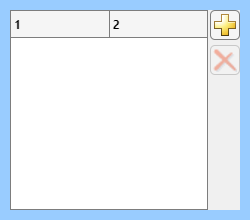

rtWidget =   RowEntriesTable with properties:

                   Data: [0×0 table]
           NewRowFormat: {["New Fruit"]  [0]}
              Orderable: off
        AllowItemRemove: [1×0 logical]
      AllowItemOrdering: [1×0 logical]
    StyleConfigurations: [0×3 table]
             TableWidth: '1x'
            TableHeight: '1x'
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [11 11 230 200]

  Show all properties


rtWidget.NewRowFormat = {"New Fruit",0}

Prepare and attach data table:

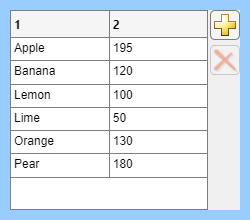

fruitData = cell2table({
    "Apple", 195
    "Banana", 120
    "Lemon", 100
    "Lime", 50
    "Orange", 130
    "Pear", 180
    }, "VariableNames", ["Name","Mass (g)"]);

rtWidget.Data = fruitData;

Optionally, place some restrictions:

rfWidget.Tooltip = "Enter the range of positive values to use (must be > 0).";
rfWidget.LowerLimitInclusive = false;
rfWidget.UpperLimitInclusive = true;
rfWidget.Limits = [0, inf];

Enable up/down buttons to reorder items:

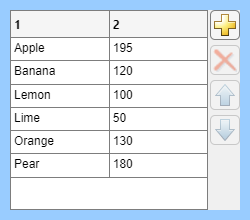

rtWidget.Orderable = true;

Add in a top row showing the overall average mass:

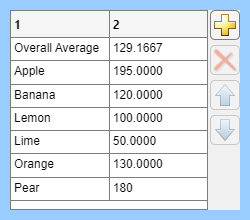

meanMass = mean(fruitData.("Mass (g)"));
fruitData = [
    {"Overall Average", meanMass}
    fruitData
    ];

rtWidget.Data = fruitData;

Finally, fix the top row to stay in place and style it:

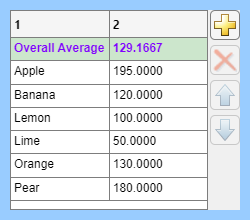

rtWidget.AllowItemRemove(1) = false;
rtWidget.AllowItemOrdering(1) = false;
firstRowStyle = uistyle("BackgroundColor",[.8 .9 .8],"FontWeight","bold","FontColor",[.5 0 1]);
rtWidget.addStyle(firstRowStyle, "row", 1)

*Copyright 2024-2025 The MathWorks, Inc.*